## **Action Viewing Modularity Notebook**

Breakdown of the pipeline to process subject fmri Data.

- Load nifti files 

- Parcellate according to Schaefer 400 (because it's popular)

- Run through multiresolution modularity for scan

- Save Networks and hyperparameters

Future Steps:

- Compare modularity across population:

- See if consistent modularity structure between groups

- Compare to reported resting state data

#### **Step 1. Load Anatomical MRI **

% clear variables
clear variables

% close figures
close all

schaefer100 = "bme8901_data/parcellations_MNI/Schaefer2018_100Parcels_17Networks_order_FSLMNI152_2mm.nii.gz";
parcels = niftiread(schaefer100);
parcels = reshape(parcels, [], 1);

**Load CIFTI and Shaefar 100 Parcellations**

%load data and parcellate
folder = '/mnt/ernie_ghassan/datasets/action_modularity/derivatives/fmriprep/'

folder = '/mnt/ernie_ghassan/datasets/action_modularity/derivatives/fmriprep/'

sub = 'sub-01/sub-01_task-action_run-1_desc-preproc_bold.nii.gz'

sub = 'sub-01/sub-01_task-action_run-1_desc-preproc_bold.nii.gz'

Vol_data = niftiread(folder+""+sub);
[nx,ny,nz, t] = size(Vol_data);
nvox = nx*ny*nz;
Vol_data = reshape(Vol_data, nx*ny*nz, t);
X = zeros(n,t);

for i=1:100
    inds = parcels == i;
    X(i,:) = mean(Vol_data(inds(1:nvox),:),1, 'omitnan');
end


X = normalize(X, 2);
[n, t] = size(X);
W = significant_correlations(X, 0.01);

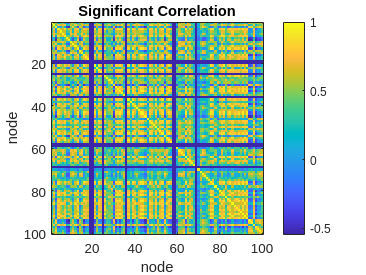

imagesc(W)
axis square; colorbar
xlabel('node')
ylabel('node')
title('Significant Correlation')

W(isnan(W)) =0;

W =     1.0000    0.5491    0.6103    0.2015    0.3378    0.4789    0.2383   -0.1384   -0.1911    0.5259    0.5867    0.4013   -0.0145    0.5276    0.5830   -0.0435    0.1974    0.2989         0         0    0.0575    0.5344    0.2541    0.1554         0    0.1096    0.3352    0.3832   -0.0255    0.5457   -0.0772    0.3102   -0.0040    0.4170    0.5033         0    0.1184    0.2729    0.0170    0.3862    0.5639    0.2729    0.0625    0.0719   -0.0919    0.4630    0.3196    0.5063    0.4032    0.2307
    0.5491    1.0000    0.3947    0.7420    0.6682    0.7194    0.7658    0.2495    0.2894    0.6472    0.4648    0.7759    0.5388    0.4239    0.6808    0.5552    0.6788    0.6103         0         0    0.6633    0.5742    0.7634    0.5792         0    0.5176    0.4881    0.6959    0.4451    0.2627    0.5529    0.7518    0.6093    0.8327    0.4577         0    0.6530    0.2396    0.5905    0.7685    0.6377    0.7744    0.6521    0.6024    0.2964    0.2836    0.7855    0.8440    0.5816    0

**Multiscale module detection**

gamma = 0.5:0.05:2.5;
Mg = zeros(n, numel(gamma));
for h = 1:numel(gamma)
    Mg(:, h) = consensus_community_louvain_with_finetuning(W, gamma(h));
end

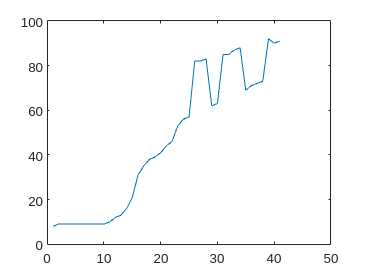

plot(max(Mg))

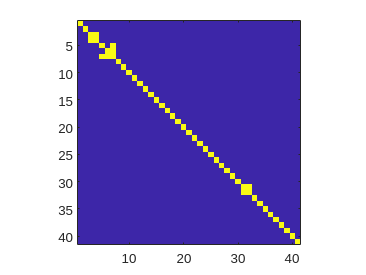

[~, nmi] = partition_distance(Mg);
imagesc(nmi==1)
axis square

**Dynamic Modularity**

l=3 % dnumber of slices I want in each slice

l = 3

XX = mat2cell(X, 100, 52*ones(1, l));

Mw = zeros(n, 12);
for h = 1:3
    W = significant_correlations(XX{h}, 0.01);
    W(W < 0) = 0;
    W(isnan(W)) = 0;
    Mw(:, h) = consensus_community_louvain_with_finetuning(W);
end

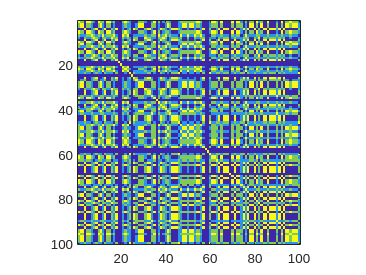

P = zeros(n);
for i = 1:l
    P = P + (Mw(:, i)==Mw(:, i)');
end
P = P / l;

M = mean(P);

imagesc(P)
axis square

function visualize_volume(volume, slices, color_limits)

clf % clear figure
tiledlayout('flow', tilespacing="none", padding="none")

% get volume dimensions
[x, y, z] = size(volume);

% loop through slices
for i = slices
    nexttile;

    % image slices
    vi = volume(:, :, i);       % get slice
    vi = rot90(vi);             % rotate 90 degrees counterclockwise
    imagesc(vi, color_limits);

    % adjust axes
    axis equal;
    axis off;
    xlim([1 x])
    ylim([1 y])
end
colorbar

end


function visualize_timeseries(X)
% function to visualize timeseries and correlation matrices

figure,
tiledlayout(2, 1)

nexttile
imagesc(X)
xlabel('timepoints')
ylabel('brain regions')
colorbar

nexttile
imagesc(corr(X'), [-0.5 0.5])
xlabel('brain regions')
ylabel('brain regions')
axis square
colorbar

end

function W = significant_correlations(X, pval)

% compute original correlation
[n, t] = size(X);
W = corr(X');

s = 1000;
P = zeros(n, n, s);
for i = 1:s
    X0 = X;

    % shuffle each column separately
    for j = 1:t
        X0(randperm(n), j) = X(1:n, j);
    end

    % compute null correlation;
    P(:, :, i) = (abs(corr(X0')) >= abs(W));
end
P = mean(P, 3);

% threshold by p value
W(P >= pval) = 0;

end



function [m1, q1_next] = community_louvain_with_finetuning(W, gamma)

if ~exist('gamma', 'var')
    gamma = 1;
end

% number of nodes
n = size(W, 1);

% initial modularity vector
m1 = 1:n;

% initial modularity values
q1_prev = -inf;
q1_next = 0;

%%% begin iterative finetuning %%%
% while modularity increases
while q1_next - q1_prev > 1e-5

    % run modularity with previous affiliation
    q1_prev = q1_next;
    [m1, q1_next] = community_louvain(W, gamma, m1, 'negative_sym');
end
%%% end iterative finetuning %%%

end



function [M, Q] = consensus_community_louvain_with_finetuning(W, gamma)

if ~exist('gamma', 'var')
    gamma = 1;
end

n = size(W, 1);
k = 100;

P = W;
while 1
    M = zeros(n, k);
    Q = zeros(1, k);
    for i = 1:k
        [M(:, i), Q(i)] = community_louvain_with_finetuning(P, gamma);
    end

    P = zeros(n);
    for i = 1:k
        P = P + (M(:, i)==M(:, i)');
    end
    P = P / k;

    if all((P==0) | (P==1))
        break
    end
end
M = M(:, 1);
Q = Q(1);

end